Michal Szabo, Afonso Fernandes, Simon Morales

15.12.2021

# Lab.3

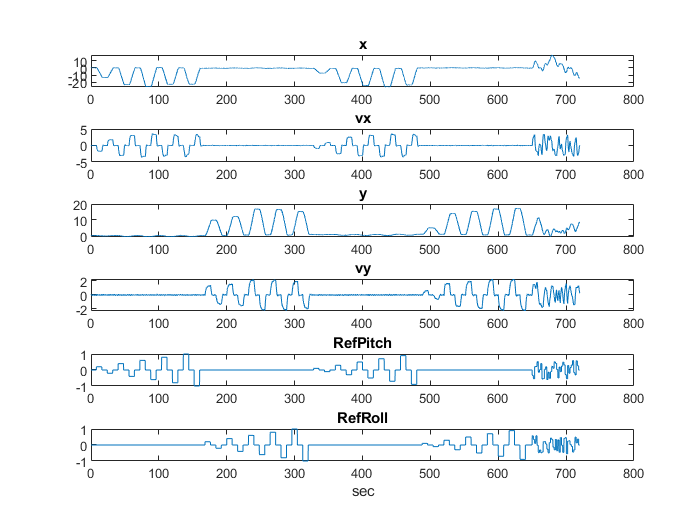

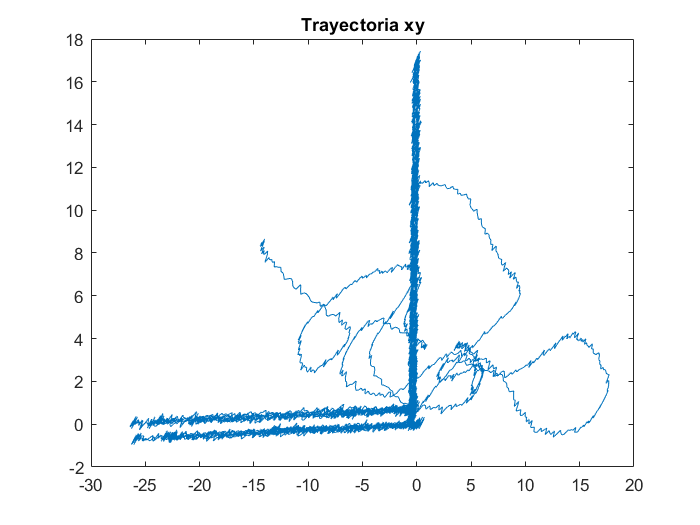

load exp_ini_fase1.txt
close all
dibujaEnsayo(exp_ini_fase1)

% Data explanation
t=exp_ini_fase1(:,1);
T = t(4)-t(3);
x=exp_ini_fase1(:,2);
vx=exp_ini_fase1(:,3);
y=exp_ini_fase1(:,4);
vy=exp_ini_fase1(:,5);
mp=exp_ini_fase1(:,6);
mr=exp_ini_fase1(:,7);

Data division

We changed our test data to validation data for simplicity

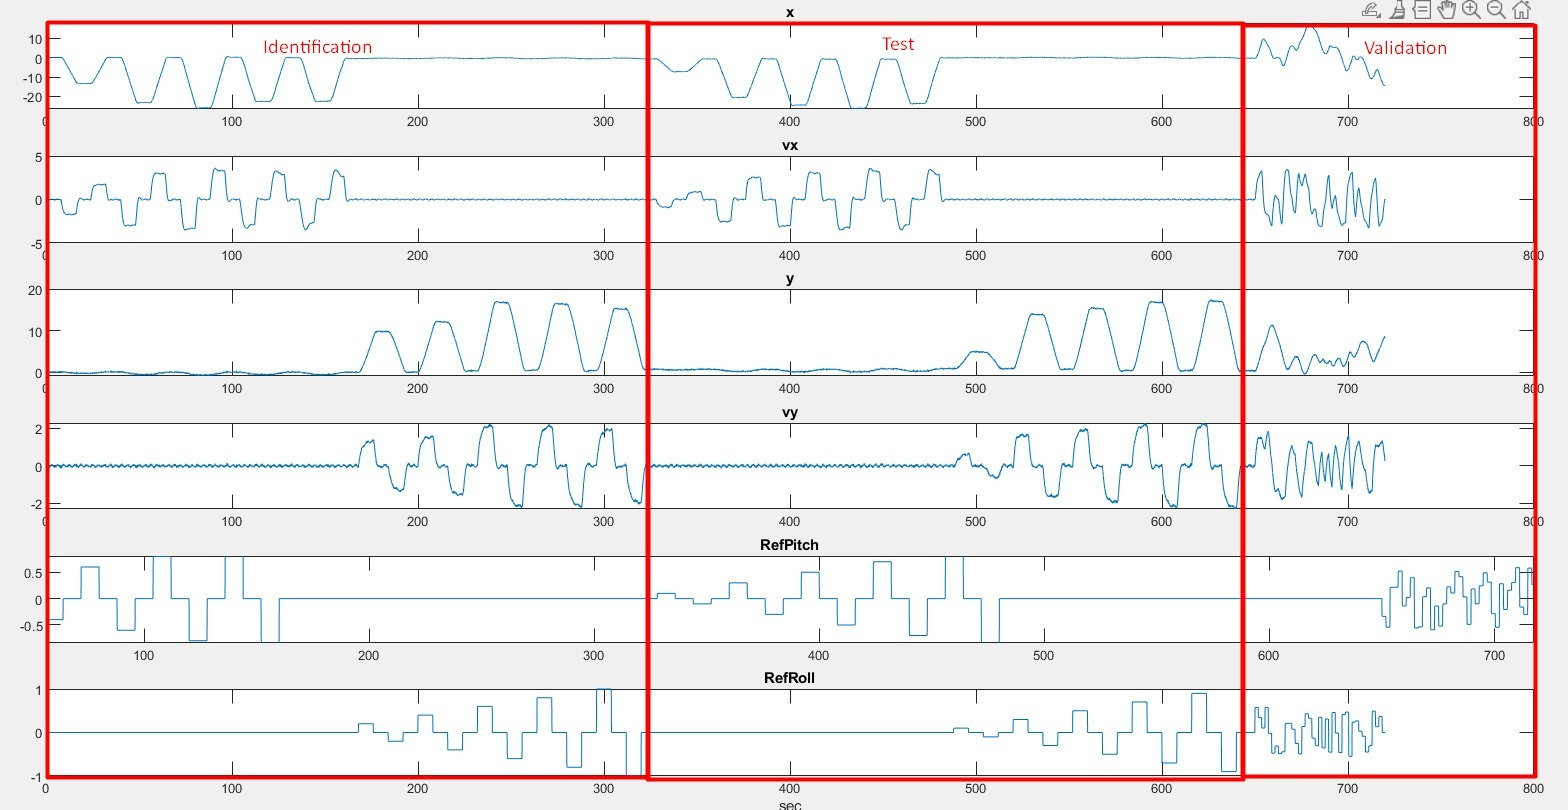

%% Data division
ident = exp_ini_fase1(1:5400,:);
valid = exp_ini_fase1(5401:10750,:);
test = exp_ini_fase1(10751:end,:);

% Identification data
x_i=ident(:,2);
vx_i=ident(:,3);
mp_i=ident(:,6);

% validation data
x_v=valid(:,2);
vx_v=valid(:,3);
mp_v=valid(:,6);


### Verification of position as being the velocity integral

sys1

na = 1; % order of polynomial A(q)
nb = 1; % order of polynomial B(q)

**Identifying delay**

We plot pitch and velocity in x and find the differece

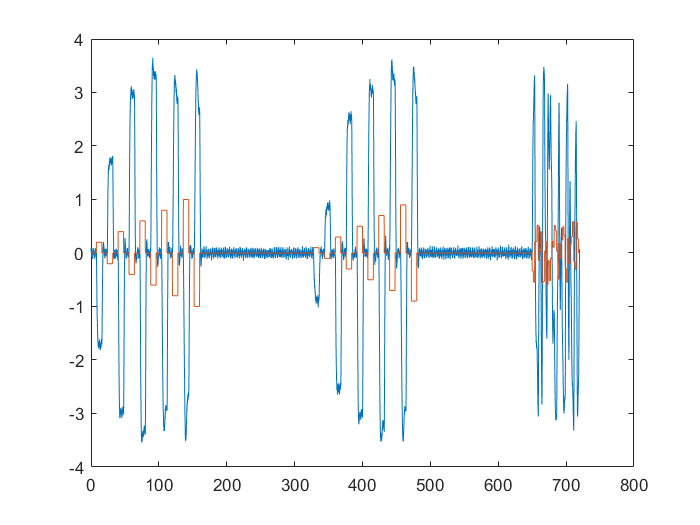

exp = exp_ini_fase1;
figure
plot(exp(:,1),exp(:,3)),hold on
plot(exp(:,1),exp(:,6)),hold off

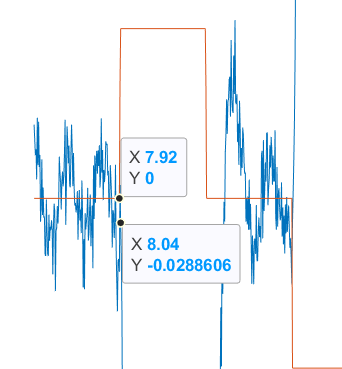

nk = (8.04-7.92)/T  % manually

nk = 2.0000

% Calculating it
id = iddata(vx,mp,T); % we need to define our iddata
nk = delayest(id) 

nk = 2

**Our system position and velocity**

na = 1; % order of polynomial A(q)
nb = 1; % order of polynomial B(q)

z = [x_i,vx_i];
sys1 = arx(z,[na nb nk])

sys1 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - z^-1                                  
                                                   
  B(z) = 0.05992 z^-2                              
                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=1   nb=1   nk=2
   Number of free coefficients: 2
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data.         
Fit to estimation data: 98.31% (prediction focus)
FPE: 0.01969, MSE: 0.01967                       


[A,B,devA,devB] = arxdata(sys1)

A =     1.0000   -0.9998


B =          0         0    0.0599


devA = 	1.0e+-3 *

         0    0.1913


devB =          0         0    0.0014


**Comparison**

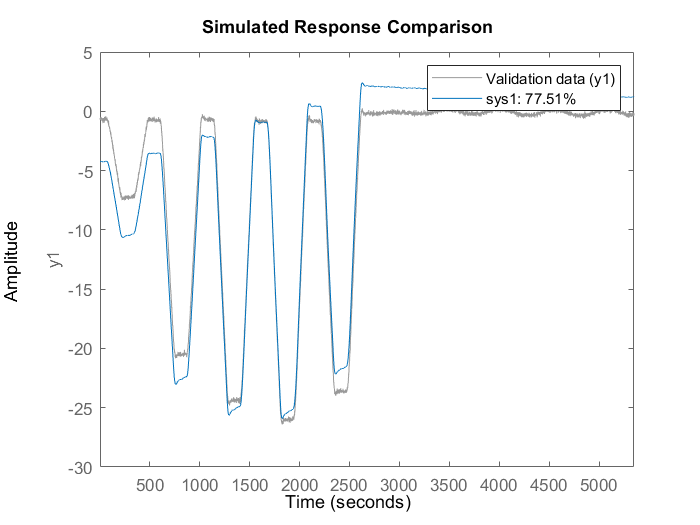

z_v = [x_v,vx_v];% validation data
compare(z_v,sys1)

**sys1**

na = 1; % order of polynomial A(q)
nb = 1; % order of polynomial B(q)

z = [vx_i,mp_i];
sys1 = arx(z,[na nb nk])

sys1 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 0.9735 z^-1                           
                                                   
  B(z) = -0.122 z^-2                               
                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=1   nb=1   nk=2
   Number of free coefficients: 2
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data.         
Fit to estimation data: 96.16% (prediction focus)
FPE: 0.002687, MSE: 0.002684                     


[A,B,devA,devB] = arxdata(sys1)

A =     1.0000   -0.9735


B =          0         0   -0.1220


devA =          0    0.0010


devB =          0         0    0.0042


**Comparison**

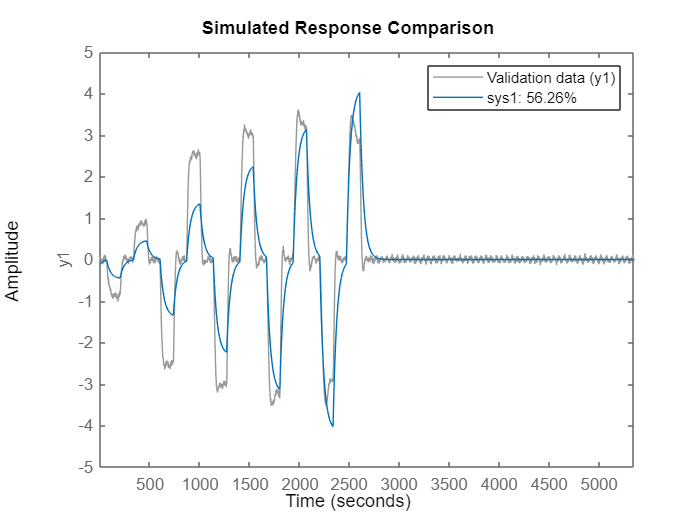

z_v = [vx_v,mp_v];% validation data
compare(z_v,sys1)

**sys2**

We tried increasing A and B while keeping the delay.

na = 2; % order of polynomial A(q)
nb = 2; % order of polynomial B(q)
nk = 2; % input-output delay

z = [vx_i,mp_i];
sys2 = arx(z,[na nb nk])

sys2 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 0.8749 z^-1 - 0.09606 z^-2            
                                                   
  B(z) = -0.07661 z^-2 - 0.05743 z^-3              
                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=2
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data.         
Fit to estimation data: 96.18% (prediction focus)
FPE: 0.002661, MSE: 0.002655                     


[A,B,devA,devB] = arxdata(sys2)

A =     1.0000   -0.8749   -0.0961


B =          0         0   -0.0766   -0.0574


devA =          0    0.0135    0.0132


devB =          0         0    0.0211    0.0216


**Comparison**

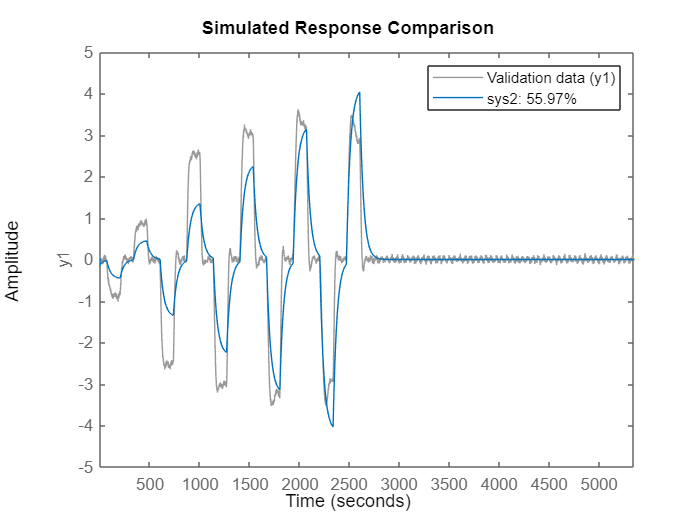

z_v = [vx_v,mp_v];% validation data
compare(z_v,sys2)

**sys3**

na = 5; % order of polynomial A(q)
nb = 5; % order of polynomial B(q)
nk = 2; % input-output delay

z = [vx_i,mp_i];
sys3 = arx(z,[na nb nk])

sys3 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                               
  A(z) = 1 - 0.716 z^-1 - 0.4543 z^-2 - 0.1645 z^-3 + 0.04588 z^-4 + 0.3045 z^-5  
                                                                                  
  B(z) = -0.07994 z^-2 + 0.01858 z^-3 - 0.07404 z^-4 + 0.02323 z^-5 + 0.04628 z^-6
                                                                                  
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=5   nb=5   nk=2
   Number of free coefficients: 10
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data.         
Fit to estimation data: 96.69% (prediction focus)
FPE: 0.002002, MSE: 0.001991                     


[A,B,devA,devB] = arxdata(sys3)

A =     1.0000   -0.7160   -0.4543   -0.1645    0.0459    0.3045


B =          0         0   -0.0799    0.0186   -0.0740    0.0232    0.0463


devA =          0    0.0130    0.0162    0.0172    0.0162    0.0126


devB =          0         0    0.0188    0.0299    0.0304    0.0299    0.0193


**Comparison**

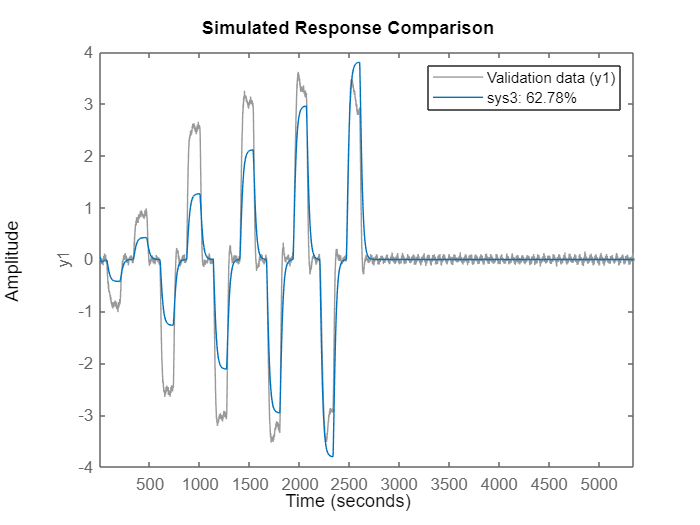

z_v = [vx_v,mp_v];% validation data
compare(z_v,sys3)